clearvars

# 4-Node Element

## Parameters

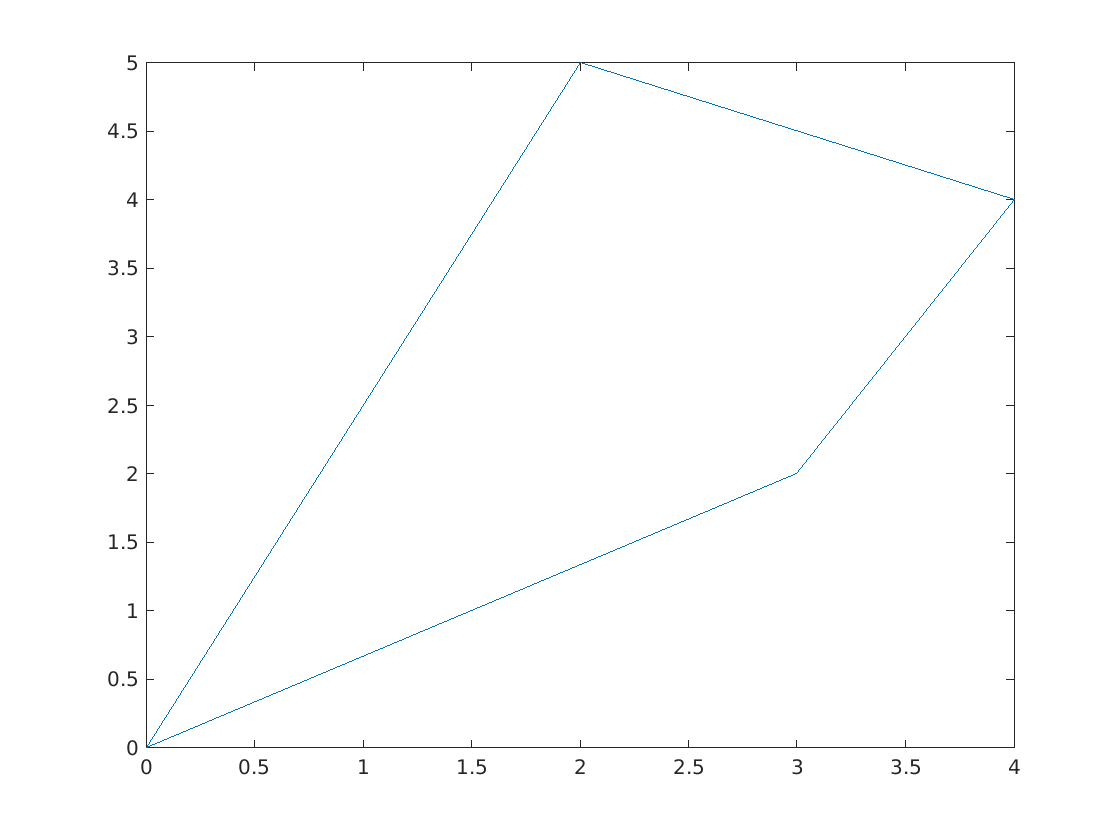

t = 1;
E = 1;
v = 0.2;
Coord1 = [
    0, 0;
    1, 0;
    1, 1;
    0, 1
];

Coord_test = [
    0, 0;
    3, 2;
    4, 4;
    2, 5
];

Coord = Coord_test;

plot([Coord(:,1); Coord(1,1)], [Coord(:,2); Coord(1,2)])

## Constitutive Law -- Plane Strain

CStrain = (E/((1 + v)*(1 - 2*v))) ...
    * [
    1 - v, v, 0;
    v, 1 - v, 0;
    0, 0, (1 - 2*v)/2
    ];

% next Plane Stress
CStress = (E/(1 + v)) ...
    * [
    1/(1 - v), v/(1 - v), 0;
    v/(1 - v), 1/(1 - v), 0;
    0, 0, 0.5
    ];

C = CStrain;

## Shape Functions

syms xi eta
N1 = (1 - xi)*(1 - eta)/4;
N2 = (1 + xi)*(1 - eta)/4;
N3 = (1 + xi)*(1 + eta)/4;
N4 = (1 - xi)*(1 + eta)/4;
Ni = [N1, N2, N3, N4];

## Coordinate Mapping

syms map
for n = 1:4
    map(n, 1) = Ni(n)*Coord(n, 1);
    map(n, 2) = Ni(n)*Coord(n, 2);
end

%    
%  (-1,1)    4--------------------3 (1,1) 
%            |                    |
%            |                    |
%            |          eta       |
%            |          |         |
%            |          --> xi    |
%            |                    |
%            |                    |
%            |                    |
%            |                    |
%  (-1,-1)   1--------------------2%   (1,-1) 
%
% newmap works korrekt
%newmap = subs(map, [xi, eta], [-1, 0])
%x = sum(newmap(:,1))
%y = sum(newmap(:,2))

x = sum(map(:,1))

$$x = \left(\eta +1\right)\,\left(\xi +1\right)-\frac{\left(\eta +1\right)\,\left(\xi -1\right)}{2}-\frac{3\,\left(\eta -1\right)\,\left(\xi +1\right)}{4}$$

y = sum(map(:,2))

$$y = \left(\eta +1\right)\,\left(\xi +1\right)-\frac{5\,\left(\eta +1\right)\,\left(\xi -1\right)}{4}-\frac{\left(\eta -1\right)\,\left(\xi +1\right)}{2}$$

CoordMap = [x, y]

$$CoordMap = \left(\begin{array}{cc} \left(\eta +1\right)\,\left(\xi +1\right)-\frac{\left(\eta +1\right)\,\left(\xi -1\right)}{2}-\frac{3\,\left(\eta -1\right)\,\left(\xi +1\right)}{4} & \left(\eta +1\right)\,\left(\xi +1\right)-\frac{5\,\left(\eta +1\right)\,\left(\xi -1\right)}{4}-\frac{\left(\eta -1\right)\,\left(\xi +1\right)}{2} \end{array}\right)$$

## Jacobian Matrix

NatCoord = [xi, eta];
for n = 1:2
    for m = 1:2
        J(n,m) = diff(CoordMap(n), NatCoord(m));
    end
end

Jinv = inv(J)';

## B Matrix

B1 = [
    1, 0, 0, 0;
    0, 0, 0, 1;
    0, 1, 1, 0
    ];

B2 = [
    Jinv(1,1), Jinv(1,2), 0, 0;
    Jinv(2,1), Jinv(2,2), 0, 0;
    0, 0, Jinv(1,1), Jinv(1,2);
    0, 0, Jinv(2,1), Jinv(2,2);
    ];

syms B3
for n = 1:4
    B3(1, 2*n - 1) = diff(Ni(n), xi);
    B3(3, 2*n) = diff(Ni(n), xi);
    B3(2, 2*n - 1) = diff(Ni(n), eta);
    B3(4, 2*n) = diff(Ni(n), eta);    
end

B = B1*B2*B3;

## Stiffness Matrix

IntFunc = ( B' * C * B )* det(J);

### Stiffnes Matrix (Actual Integration)

% ke = t * int(int(IntFunc, xi, -1, 1), eta, -1, 1); 
% double(ke)

high computation time!!!

### Stiffness Matrix (Full Gauss Integration)

xiset = [1/sqrt(3), -1/sqrt(3)];
etaset = [1/sqrt(3), -1/sqrt(3)];

kFull = 0;

for n = 1:2
    for m = 1:2
        kSmall = subs(IntFunc, [xi, eta], [xiset(n), etaset(m)]);
        kFull = kFull + kSmall;
    end
end

kFull = kFull * t;
double(kFull)

ans =     0.4020    0.0449   -0.5482    0.1006   -0.1572   -0.1096    0.3034   -0.0359
    0.0449    0.2165    0.1700   -0.1725   -0.1096   -0.0097   -0.1054   -0.0343
   -0.5482    0.1700    1.2045   -0.4637   -0.0393   -0.0148   -0.6170    0.3084
    0.1006   -0.1725   -0.4637    1.1362    0.0546   -0.3239    0.3084   -0.6398
   -0.1572   -0.1096   -0.0393    0.0546    0.6957   -0.0327   -0.4992    0.0877
   -0.1096   -0.0097   -0.0148   -0.3239   -0.0327    0.4647    0.1571   -0.1311
    0.3034   -0.1054   -0.6170    0.3084   -0.4992    0.1571    0.8128   -0.3602
   -0.0359   -0.0343    0.3084   -0.6398    0.0877   -0.1311   -0.3602    0.8053


### Stiffness Matrix (Reduced Gauss Integration)

kReduced = t * (2*2) * subs(IntFunc, [xi, eta], [0, 0]); 
double(kReduced)

ans =     0.3255    0.0651   -0.3646    0.0521   -0.3255   -0.0651    0.3646   -0.0521
    0.0651    0.1519    0.1215   -0.0174   -0.0651   -0.1519   -0.1215    0.0174
   -0.3646    0.1215    0.7639   -0.3472    0.3646   -0.1215   -0.7639    0.3472
    0.0521   -0.0174   -0.3472    0.7639   -0.0521    0.0174    0.3472   -0.7639
   -0.3255   -0.0651    0.3646   -0.0521    0.3255    0.0651   -0.3646    0.0521
   -0.0651   -0.1519   -0.1215    0.0174    0.0651    0.1519    0.1215   -0.0174
    0.3646   -0.1215   -0.7639    0.3472   -0.3646    0.1215    0.7639   -0.3472
   -0.0521    0.0174    0.3472   -0.7639    0.0521   -0.0174   -0.3472    0.7639
